# 測定回数と相関係数

同じ確率分布に従う独立な乱数を2組生成する．

観測数によって相関係数がどの程度変わるのかを数値実験する．

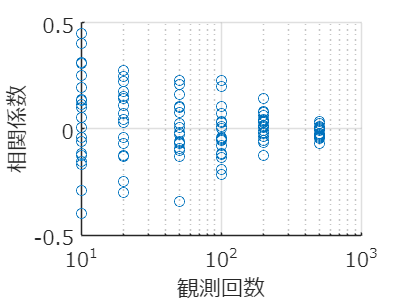

rng(1)
outData=[];
for N=[10,20,50,100,200,500]
    for k=1:20
        x=randn(N,1);
        y=randn(N,1);
        outData=[outData;
            N, corr(x,y)];
    end
end

figure
scatter(outData(:,1),outData(:,2));
set(gca,'xscale','log');grid on;
set(gca,'fontname','メイリオ','fontsize',12);
xlabel('観測回数');
ylabel('相関係数');
exportgraphics(gcf,'fig_pseudoCorr.pdf');